# Fit a Polynomial

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

dates = readmatrix("./data/electricityData.xlsx", Sheet="dates", OutputType="datetime");
usage = readmatrix("./data/electricityData.xlsx", Sheet="usage");
residential = usage(:, 1);
whos

  Name               Size            Bytes  Class       Attributes

  dates            315x1              2520  datetime              
  residential      315x1              2520  double                
  usage            315x4             10080  double                



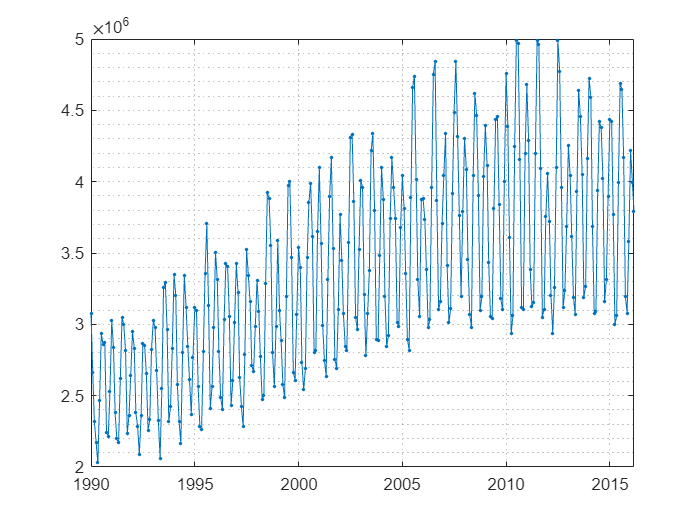

plot(dates, residential, ".-")
grid minor

## Task 1

The datetime vector `dates` contains the months for which the electricity usage is recorded. To perform polynomial fitting, you must first convert the dates to elapsed times.

You can perform arithmetic operations on dates. The result will be a `duration` variable.

`dur` `=` `t1` `-` `t2`

You can use functions such as `days`, `hours`, and so on, to convert a duration into a numeric value that represents that duration in the appropriate units.

`numdays` `=` `days``(``dur``)`

t = days(dates - dates(1))

t =      0
    31
    59
    90
   120
   151
   181
   212
   243
   273


## Task 2

[c, ~, sc] = polyfit(t, residential, 3)

c = 1.0e+06 *

   -0.0771   -0.1088    0.5904    3.4655


sc = 1.0e+03 *

    4.7779
    2.7722


resFit = polyval(c, t, [], sc)

resFit = 1.0e+06 *

    2.5197
    2.5228
    2.5257
    2.5290
    2.5322
    2.5357
    2.5390
    2.5426
    2.5462
    2.5498


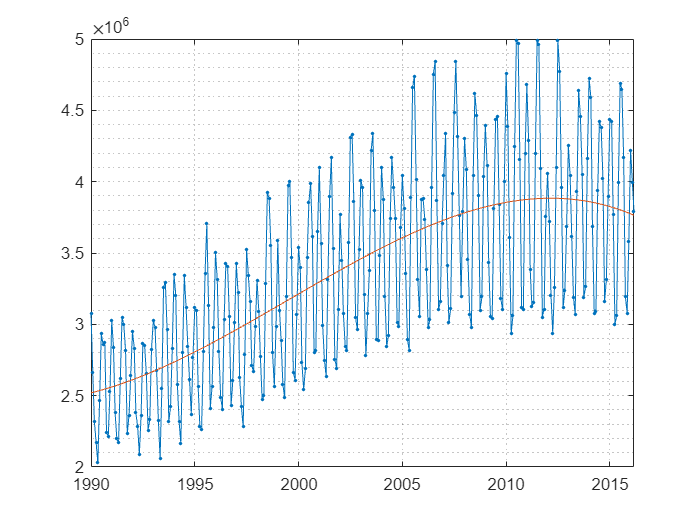

hold on
plot(dates, resFit)
hold off